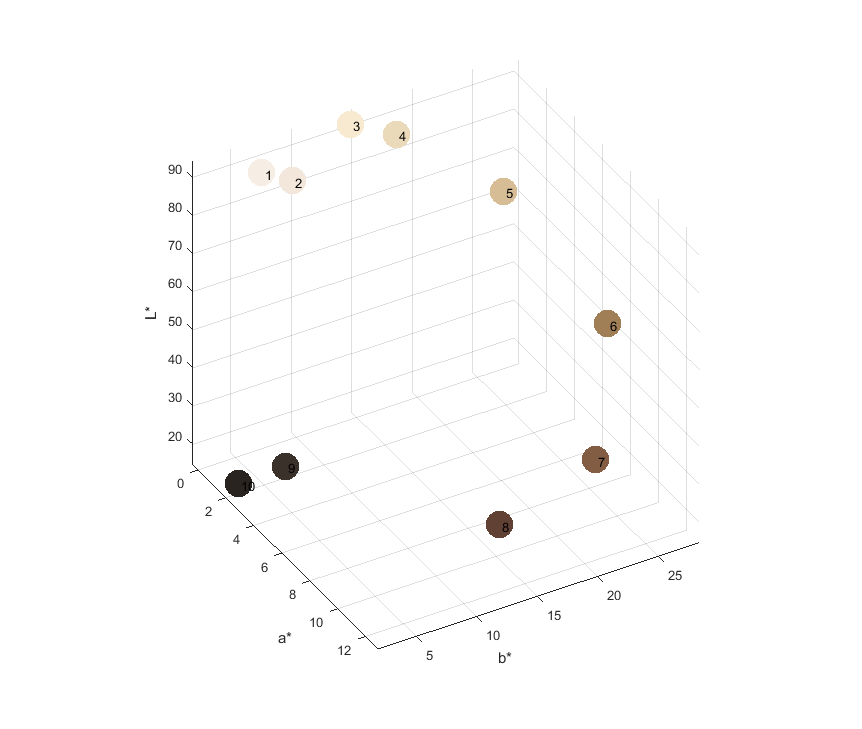

myrgb = zeros(10,3);
myrgb(1,:) = rgb(246, 237, 228);
myrgb(2,:) = rgb(243, 231, 219);
myrgb(3,:) = rgb(247, 234, 208);
myrgb(4,:) = rgb(234, 218, 186);
myrgb(5,:) = rgb(215, 189, 150);
myrgb(6,:) = rgb(160, 126, 86);
myrgb(7,:) = rgb(130, 92, 67);
myrgb(8,:) = rgb(96, 65, 52);
myrgb(9,:) = rgb(58, 49, 42);
myrgb(10,:) = rgb(41, 36, 32);

mylab = rgb2lab(myrgb/255);
dist = 0.1;

clf
hg = gcf;
set(gcf,'Visible','on')
hold on
for i=1:10
    plot3(mylab(i,2),mylab(i,3),mylab(i,1),'o','MarkerSize',20,'MarkerFaceColor',myrgb(i,:)/255,'MarkerEdgeColor',myrgb(i,:)/255)
    text(mylab(i,2)+dist,mylab(i,3)+dist,mylab(i,1),sprintf('%d',i))
end
xlabel('a*')
ylabel('b*')
zlabel('L*')
grid on
view(60,35)

create_animation ('test')

function val = rgb (r,g,b)
    val = [r g b];
end

